# Fixed Wing Control Design

Define parameters:

clc
clear

parameters

Va0=P.Va0;
g=P.g;
rho=1.225;

beta0=0;
alpha0=0;

Prop_R = sqrt(P.Sprop/pi);
Prop_diam = 2*Prop_R;

Fuel_density = (775.0 + 840.0) / 2; % density of Jet A-1 fuel (kg/m^3)
%https://code7700.com/fuel_density.htm

Fuel_L = P.Fuel_Cap_L /2 ; % amount of fuel in L -> half a tank
W_fuel_half = (Fuel_L/1000)*Fuel_density*P.gravity; % weight of gas in N

Weight = (P.m * P.gravity) + W_fuel_half;

AR = P.b/P.c;
K = 1 / (pi*P.e*AR);

dyn_pressure = (1/2)*rho*(Va0)^2;
CL = Weight / (dyn_pressure*P.S);
CD = P.C_Do + K*CL^2;

% physical parameters of airframe

m=P.m;
Ixx=P.Ixx;
Iyy=P.Iyy;
Izz=P.Izz;
Ixz=P.Ixz;
S=P.S;
b=P.b;
c=P.c;
Sprop=P.Sprop;
e=P.e;
Omega_max=P.OmegaMax_RPM; % rad/s
FuelCapacity=P.Fuel_Cap_L; % L

% Longitudinal

Cl0=P.C_Lo;
CD0=P.C_Do;
Cm0=P.C_mo;
Clalpha=P.C_Lalpha;
CDalpha=P.C_Dalpha;
Cmalpha=P.C_malpha;
Clq=P.C_Lq;
CDq=P.C_Dq;
Cmq=P.C_mq;
Cldelta_e=P.C_Ldelta_e;
CDdelta_e=P.C_Ddelta_e_;
Cmdelta_e=P.C_mdelta_e_;
epsilon=P.C_Epsilon;

% Lateral

CY0=P.C_Yo;
Cl0=P.C_lo;
Cn0=P.C_no;
CYbeta=P.C_Ybeta;
Clbeta=P.C_lbeta;
Cnbeta=P.C_nbeta;
CYp=P.C_Yp;
Clp=P.C_lp;
Cnp=P.C_np;
CYr=P.C_Yr;
Clr=P.C_lr;
Cnr=P.C_nr;
CYdelta_a=P.C_Ydelta_a;
Cldelta_a=P.C_ldelta_a;
Cndelta_a=P.C_ndelta_a;
CYdelta_r=P.C_Ydelta_r;
Cldelta_r=P.C_ldelta_r;
Cndelta_r=P.C_ndelta_r;

% compute inertial constants

K = Ixx*Izz-Ixz^2;
k1 = Ixz*(Ixx-Iyy+Izz)/K;
k2 = (Izz*(Izz-Iyy)+Ixz^2)/K;
k3 = Izz/K;
k4 = Ixz/K;
k5 = (Izz-Ixx)/Iyy;
k6 = Ixz/Iyy;
k7 = ((Ixx-Iyy)*Ixx+Ixz^2)/K;
k8 = Ixx/K;

% Additional Coefficients

Cp0=k3*Cl0+k4*Cn0;
Cpbeta=k3*Clbeta+k4*Cnbeta;
Cpp=k3*Clp+k4*Cnp;
Cpr=k3*Clr+k4*Cnr;
Cpdelta_a=k3*Cldelta_a+k4*Cndelta_a;
Cpdelta_r=k3*Cldelta_r+k4*Cndelta_r;
Cr0=k4*Cl0+k8*Cn0;
Crbeta=k4*Clbeta+k8*Cnbeta;
Crp=k4*Clp+k8*Cnp;
Crr=k4*Clr+k8*Cnr;
Crdelta_a=k4*Cldelta_a+k8*Cndelta_a;
Crdelta_r=k4*Cldelta_r+k8*Cndelta_r;

CX0=-CD*cos(alpha0)+CL*sin(alpha0);
CXalpha=CX0;  % ???
CXq=-CDq*cos(alpha0)+Clq*sin(alpha0);
CXdelta_e=-CDdelta_e*cos(alpha0)+Cldelta_e*sin(alpha0);
CZ0=-CD*sin(alpha0)-CL*cos(alpha0);
CZalpha=CZ0; % ???
CZq=-CDq*sin(alpha0)-Clq*cos(alpha0);
CZdelta_e=-CDdelta_e*sin(alpha0)-Cldelta_e*cos(alpha0);

% Initial Conditions

pn0=P.pn0;
pe0=P.pe0;
pd0=P.pd0;
u0=P.u0;
v0=P.v0;
w0=P.w0;
phi0=P.phi0;
theta0=P.theta0;
psi0=P.psi0;
p0=P.p0;
q0=P.q0;
r0=P.r0;
delta_e0=P.delta_e0;
delta_a0=P.delta_a0;
delta_r0=P.delta_r0;
delta_t0=P.delta_t0;

% Longitudinal Aerodynamic Derivatives

Xu=(u0*rho*S)/m*(CX0+CXalpha*alpha0+CXdelta_e*delta_e0)-(rho*S*w0*CXalpha)/(2*m)+(rho*S*c*CXq*u0*q0)/(4*m*Va0)-(rho*Sprop*u0)/m;
Xw=-q0+(w0*rho*S)/m*(CX0+CXalpha*alpha0+CXdelta_e*delta_e0)+(rho*S*c*CXq*w0*q0)/(4*m*Va0)+(rho*S*CXalpha*u0)/(2*m)-(rho*Sprop*w0)/m;
Xq=-w0+(rho*Va0*S*CXq*c)/(4*m);
Xdelta_e=(rho*Va0^2*S*CXdelta_e)/(2*m);
Xdelta_t=(rho*Sprop*delta_t0^2)/m;

Zu=q0+(u0*rho*S)/m*(CZ0+CZalpha*alpha0+CZdelta_e*delta_e0)-(rho*S*w0*CZalpha)/(2*m)+(rho*S*c*CZq*u0*q0)/(4*m*Va0);
Zw=(w0*rho*S)/m*(CZ0+CZalpha*alpha0+CZdelta_e*delta_e0)+(rho*S*c*CZq*w0*q0)/(4*m*Va0)+(rho*S*CZalpha*u0)/(2*m);
Zq=u0+(rho*Va0*S*CZq*c)/(4*m);
Zdelta_e=(rho*Va0^2*S*CZdelta_e)/(2*m);

Mu=(u0*rho*S*c)/Iyy*(Cm0+Cmalpha*alpha0+Cmdelta_e*delta_e0)+(rho*S*c*Cmalpha*w0)/(2*Iyy)+(rho*S*c^2*Cmq*q0*u0)/(4*Iyy*Va0);
Mw=(w0*rho*S*c)/Iyy*(Cm0+Cmalpha*alpha0+Cmdelta_e*delta_e0)+(rho*S*c*Cmalpha*u0)/(2*Iyy)+(rho*S*c^2*Cmq*q0*w0)/(4*Iyy*Va0);
Mq=(rho*Va0*S*c^2*Cmq)/(4*Iyy);
Mdelta_e=(rho*Va0*2*S*c*Cmdelta_e)/(2*Iyy);

% Lateral Aerodynamic Derivatives

Yv=(rho*S*b*v0)/(4*m*Va0)*(CYp*p0+CYr*r0)+(rho*S*v0)/m*(CY0+CYbeta*beta0+CYdelta_a*delta_a0+CYdelta_r*delta_r0)+(rho*S*CYbeta)/(2*m)*sqrt(u0^2+w0^2);
Yp=w0+(rho*Va0*S*b)/(4*m)*CYp;
Yr=-u0+(rho*Va0*S*b)/(4*m)*CYdelta_r;
Ydelta_a=(rho*Va0^2*S)/(2*m)*CYdelta_a;
Ydelta_r=(rho*Va0^2*S)/(2*m)*CYdelta_r;

Lv=(rho*S*b^2*v0^2)/(4*Va0)*(Cpp*p0+Cpr*r0)+rho*S*b*v0*(Cp0+Cpbeta*beta0+Cpdelta_a*delta_a0+Cpdelta_r*delta_r0)+(rho*S*b*Cpbeta)/2*sqrt(u0^2+v0^2);
Lp=k1*q0+(rho*Va0*S*b^2)/4*Cpp;
Lr=-k2*q0+(rho*Va0*S*b^2)/4*Cpr;
Ldelta_a=(rho*Va0^2*S*b)/2*Cpdelta_a;
Ldelta_r=(rho*Va0^2*S*b)/2*Cpdelta_r;

Nv=(rho*S*b^2*v0^2)/(4*Va0)*(Crp*p0+Crr*r0)+rho*S*b*v0*(Cr0+Crbeta*beta0+Crdelta_a*delta_a0+Crdelta_r*delta_r0)+(rho*S*b*Crbeta)/2*sqrt(u0^2+v0^2);
Np=k7*q0+(rho*Va0*S*b^2)/4*Crp;
Nr=-k1*q0+(rho*Va0*S*b^2)/4*Crr;
Ndelta_a=(rho*Va0^2*S*b)/2*Crdelta_a;
Ndelta_r=(rho*Va0^2*S*b)/2*Crdelta_r;


Longitudinal Model:

% Replace 1 with Xdelta_t in B_long(1,2)

A_long=[Xu Xw Xq -g*cos(theta0) 0;...
    Zu Zw Zq -g*sin(theta0) 0;...
    Mu Mw Mq 0 0;
    0 0 1 0 0;
    sin(theta0) -cos(theta0) 0 u0*cos(theta0)+w0*sin(theta0) 0]

A_long =    -0.2717   -0.0475         0   -9.8100         0
   -1.5310   -0.7655   15.0000         0         0
   -0.0404   -0.3213   -0.2891         0         0
         0         0    1.0000         0         0
         0   -1.0000         0   15.0000         0



B_long=[Xdelta_e 1; Zdelta_e 0; Mdelta_e 0; 0 0; 0 0]

B_long =          0    1.0000
    2.0212         0
   -0.8456         0
         0         0
         0         0



A1=[A_long B_long;...
    zeros(2,5) [-10 0; 0 -1/3.5]]

A1 =    -0.2717   -0.0475         0   -9.8100         0         0    1.0000
   -1.5310   -0.7655   15.0000         0         0    2.0212         0
   -0.0404   -0.3213   -0.2891         0         0   -0.8456         0
         0         0    1.0000         0         0         0         0
         0   -1.0000         0   15.0000         0         0         0
         0         0         0         0         0  -10.0000         0
         0         0         0         0         0         0   -0.2857



B1=[zeros(5,2); [10 0; 0 1/3.5]]

B1 =          0         0
         0         0
         0         0
         0         0
         0         0
   10.0000         0
         0    0.2857



C1=eye(5);

F1=zeros(5,2);

E1=zeros(7,2);

% Select Q and R

Q1=0.0001;
R1=100;

% Open loop system

sys1=ss(A_long,B_long,C1,F1);

% Design controller

[Y1,P1,CLP1]=lqr(sys1,Q1,R1);
% [X1,S]=linsolve(C1',Y1');
% K1=X1';
K1=Y1

K1 =     0.0276    0.0375   -0.1939   -0.5780    0.0008
    0.0190   -0.0027   -0.0391   -0.0154    0.0006


K1_ss=K1(:,1:5)

K1_ss =     0.0276    0.0375   -0.1939   -0.5780    0.0008
    0.0190   -0.0027   -0.0391   -0.0154    0.0006


% K1_J=K1(:,6:7)

Long_ICs=[Va0; 0; 0; 0; -pd0; 0; 0];

A1_sim=A1(1:5,1:5);
B1_sim=B1(1:5,1:2);
C1_sim=C1(1:5,1:5);
D1_sim=zeros(5,2);

% Closed loop system

Ac1=A1_sim-B_long*K1;
Bc1=E1-B1*K1*F1;
% Bc1=B1;

ss_closed1=ss(Ac1,B_long,C1,F1);

% Simulation

amp=stepDataOptions;
amp.StepAmplitude=[20 500];
t=0:0.01:100;
[y,tt,x]=step(ss_closed1,t,amp);
x1=y(:,1,1);
x2=y(:,5,2);

figure(2)
subplot(2,1,1)
plot(t,x1)
grid
title('Speed');
ylabel('u');

subplot(2,1,2)
plot(t,x2)
grid
title('Height');
xlabel('time (s)');
ylabel('h');

Lateral Model:

A_latr=[Yv Yp Yr g*cos(theta0)*cos(phi0) 0;...
    Lv Lp Lr 0 0;...
    Nv Np Nr 0 0;...
    0 1 cos(phi0)*tan(theta0) q0*cos(phi0)*tan(theta0)-r0*sin(phi0)*tan(theta0) 0;...
    0 0 cos(phi0)*sec(theta0) p0*cos(phi0)*sec(theta0)-r0*sin(phi0)*sec(theta0) 0]

A_latr =    -0.3668         0  -15.0921    9.8100         0
   -1.8445   -6.7094    3.0120         0         0
    1.9533   -0.1943   -4.0090         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0



B_latr=[Ydelta_a Ydelta_r; Ldelta_a Ldelta_r; Ndelta_a Ndelta_r; 0 0; 0 0]

B_latr =          0   -0.9545
   22.6176   27.6471
    9.0346   -2.1004
         0         0
         0         0


**Longitudinal Response:**

% Laplace transform of longitudinal model

syms s

tf_matrix_long=vpa(simplify(inv(s*eye(5)-A_long)*B_long));

Gu_delta_p

% Obtain transfer function from state space

Gu_delta_p=tf_matrix_long(1,2);
[n1,d1]=numden(Gu_delta_p);
[ncoefs1,pwr1]=coeffs(n1);
n1=sym2poly(vpa((n1/ncoefs1(1)),4));
d1=sym2poly(vpa((d1/ncoefs1(1)),4));

Gu_delta_p=tf(n1,d1)

Gu_delta_p =
 
            s^3 + 1.055 s^2 + 5.041 s
  ----------------------------------------------
  s^4 + 1.326 s^3 + 5.255 s^2 + 0.9235 s + 4.523
 
Continuous-time transfer function.




% Observe the open loop step response of the system and the closed loop response.

disp('Fig 1. Open-Loop Step Response Before PID:');

Fig 1. Open-Loop Step Response Before PID:


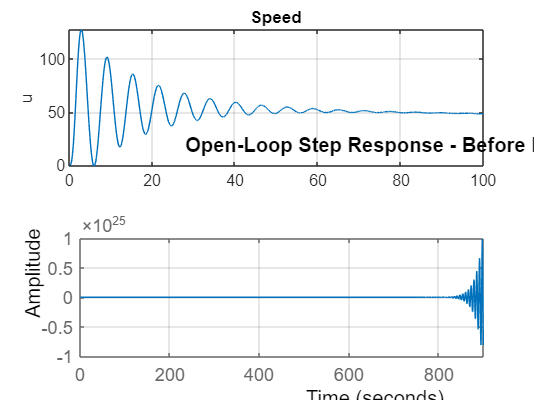

step(Gu_delta_p)
title('Open-Loop Step Response - Before PID');
grid


disp('Fig 2. Closed-Loop Step Response Before PID:');

Fig 2. Closed-Loop Step Response Before PID:


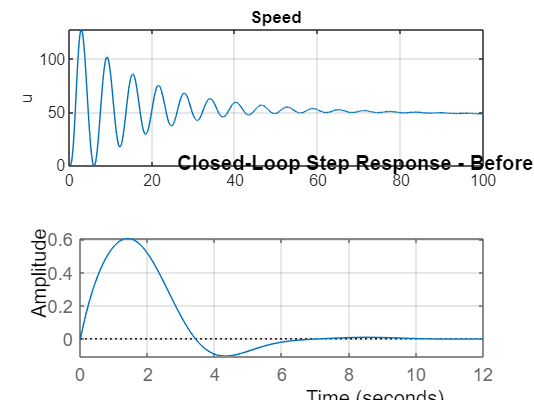

step(feedback(Gu_delta_p,1))
title('Closed-Loop Step Response - Before PID');
grid


% pidTuner(Gu_delta_p,'pid')

% Set Kp, Ki, and Kd values and create feedback loop

Kp1=15.42;
Ki1=71.6;
Kd1=0.08143;
Cp1=pid(Kp1,Ki1,Kd1);
T1=feedback(Cp1*Gu_delta_p,1);

t=0:0.01:100;
disp('Fig 3. Closed-Loop Step Response After PID:');

Fig 3. Closed-Loop Step Response After PID:


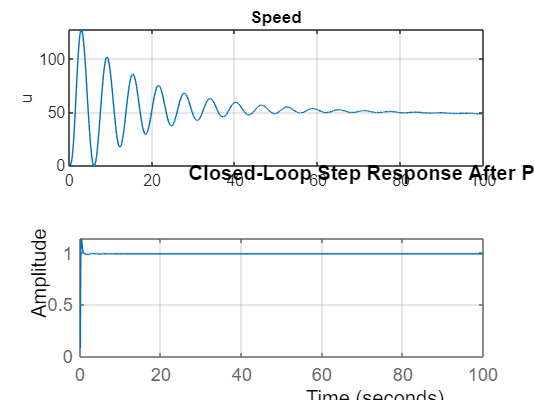

step(T1,t);
title('Closed-Loop Step Response After PID:');
grid

stepinfo(T1)

ans = struct with fields:
         RiseTime: 0.098381
    TransientTime: 0.71459
     SettlingTime: 0.70137
      SettlingMin: 0.89413
      SettlingMax: 1.1374
        Overshoot: 15.16
       Undershoot: 0
             Peak: 1.1374
         PeakTime: 0.25986



% Steady state error

[y1,t]=step(T1);
ss_error1=abs(1-y1(end))

ss_error1 =      0.013455


Gtheta_delta_e

% Obtain transfer function from state space

Gtheta_delta_e=tf_matrix_long(4,1);
[n2,d2]=numden(Gtheta_delta_e);
[ncoefs2,pwr2]=coeffs(n2);
n2=sym2poly(vpa((n2/ncoefs1(1)),4));
d2=sym2poly(vpa((d2/ncoefs1(1)),4));

Gtheta_delta_e=tf(n2,d2)

Gtheta_delta_e =
 
          -0.8456 s^2 - 1.527 s - 0.2869
  ----------------------------------------------
  s^4 + 1.326 s^3 + 5.255 s^2 + 0.9235 s + 4.523
 
Continuous-time transfer function.




% Observe the open loop step response of the system and the closed loop response.

disp('Fig 4. Open-Loop Step Response Before PID:');

Fig 4. Open-Loop Step Response Before PID:


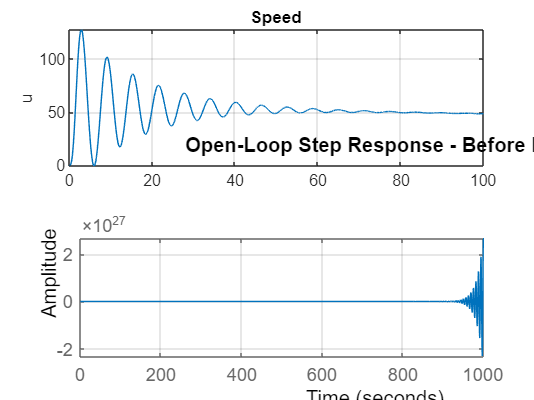

step(Gtheta_delta_e)
title('Open-Loop Step Response - Before PID');
grid


disp('Fig 5. Closed-Loop Step Response Before PID:');

Fig 5. Closed-Loop Step Response Before PID:


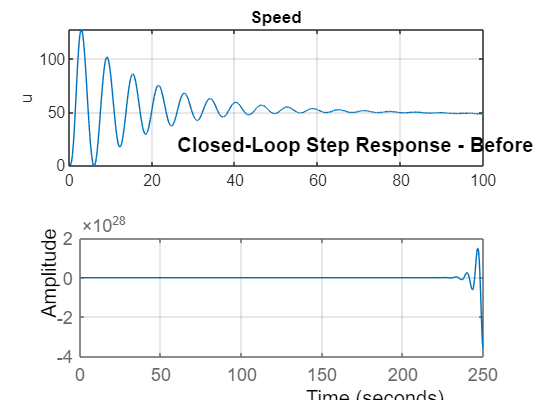

step(feedback(Gtheta_delta_e,1))
title('Closed-Loop Step Response - Before PID');
grid


% pidTuner(Gtheta_delta_e,'pid')

% Set Kp, Ki, and Kd values and create feedback loop

Kp2=-158.1;
Ki2=-218.6;
Kd2=-28.59;
Cp2=pid(Kp2,Ki2,Kd2);
T2=feedback(Cp2*Gtheta_delta_e,1);

t=0:0.01:100;
disp('Fig 3. Closed-Loop Step Response After PID:');

Fig 3. Closed-Loop Step Response After PID:


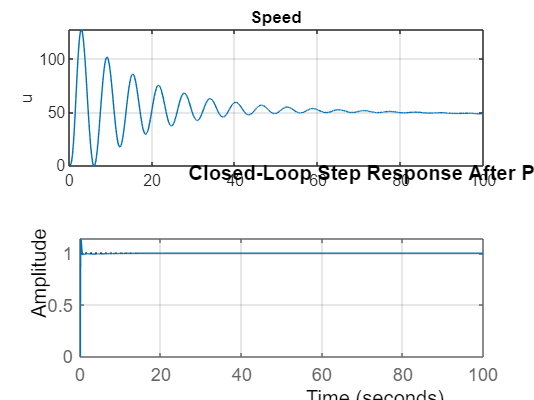

step(T2,t);
title('Closed-Loop Step Response After PID:');
grid

stepinfo(T2)

ans = struct with fields:
         RiseTime: 0.060133
    TransientTime: 0.40709
     SettlingTime: 0.40709
      SettlingMin: 0.91059
      SettlingMax: 1.1427
        Overshoot: 14.275
       Undershoot: 0
             Peak: 1.1427
         PeakTime: 0.168



% Steady state error

[y2,t]=step(T2);
ss_error2=abs(1-y2(end))

ss_error2 =       0.01492


**Lateral Response:**

% Laplace transform of lateral model

syms s

tf_matrix_latr=vpa(simplify(inv(s*eye(5)-A_latr)*B_latr));

Gphi_delta_a

% Obtain transfer function from state space

Gphi_delta_a=tf_matrix_latr(4,1);
[n3,d3]=numden(Gphi_delta_a);
[ncoefs3,pwr3]=coeffs(n3);
n3=sym2poly(vpa((n3/ncoefs3(1)),4));
d3=sym2poly(vpa((d3/ncoefs3(1)),4));

Gphi_delta_a=tf(n3,d3)

Gphi_delta_a =
 
                   s^2 + 5.579 s + 42.51
  -------------------------------------------------------
  0.04421 s^4 + 0.4901 s^3 + 2.692 s^2 + 10.23 s + 0.6555
 
Continuous-time transfer function.




% Observe the open loop step response of the system and the closed loop response.

disp('Fig 7. Open-Loop Step Response Before PID:');

Fig 7. Open-Loop Step Response Before PID:


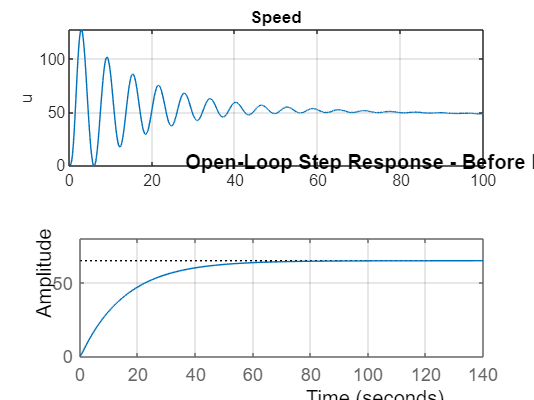

step(Gphi_delta_a)
title('Open-Loop Step Response - Before PID');
grid


disp('Fig 8. Closed-Loop Step Response Before PID:');

Fig 8. Closed-Loop Step Response Before PID:


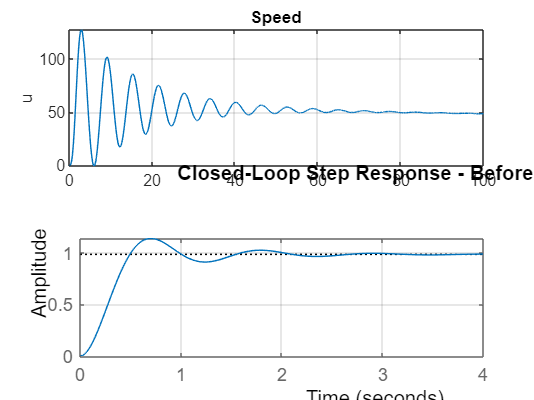

step(feedback(Gphi_delta_a,1))
title('Closed-Loop Step Response - Before PID');
grid


% pidTuner(Gphi_delta_a,'pid')

% Set Kp, Ki, and Kd values and create feedback loop

Kp3=0.02211;
Ki3=0.002535;
Kd3=0;
Cp3=pid(Kp3,Ki3,Kd3);
T3=feedback(Cp3*Gphi_delta_a,1);

t=0:0.01:100;
disp('Fig 9. Closed-Loop Step Response After PID:');

Fig 9. Closed-Loop Step Response After PID:


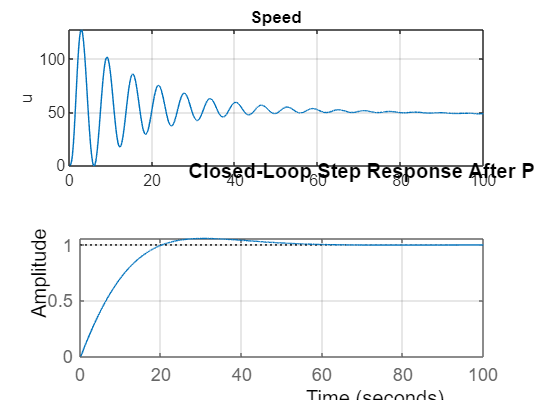

step(T3,t);
title('Closed-Loop Step Response After PID:');
grid

stepinfo(T3)

ans = struct with fields:
         RiseTime: 14.079
    TransientTime: 48.807
     SettlingTime: 48.807
      SettlingMin: 0.90891
      SettlingMax: 1.0582
        Overshoot: 5.8182
       Undershoot: 0
             Peak: 1.0582
         PeakTime: 30.662



% Steady state error

[y3,t]=step(T3);
ss_error3=abs(1-y3(end))

ss_error3 =     0.0012105


Gv_delta_r

% Obtain transfer function from state space

Gv_delta_r=tf_matrix_latr(1,2);
[n4,d4]=numden(Gv_delta_r);
[ncoefs4,pwr4]=coeffs(n4);
n4=sym2poly(vpa((n4/ncoefs4(1)),4));
d4=sym2poly(vpa((d4/ncoefs4(1)),4));

Gv_delta_r=tf(n4,d4)

Gv_delta_r =
 
          -s^3 + 22.49 s^2 + 564.4 s + 1074
  --------------------------------------------------
  1.048 s^4 + 11.61 s^3 + 63.8 s^2 + 242.4 s + 15.53
 
Continuous-time transfer function.




% Observe the open loop step response of the system and the closed loop response.

disp('Fig 10. Open-Loop Step Response Before PID:');

Fig 10. Open-Loop Step Response Before PID:


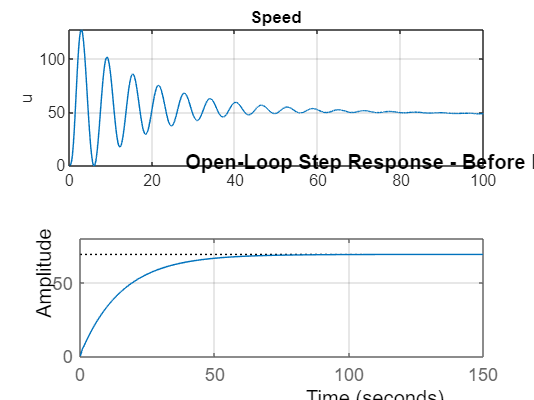

step(Gv_delta_r)
title('Open-Loop Step Response - Before PID');
grid


disp('Fig 11. Closed-Loop Step Response Before PID:');

Fig 11. Closed-Loop Step Response Before PID:


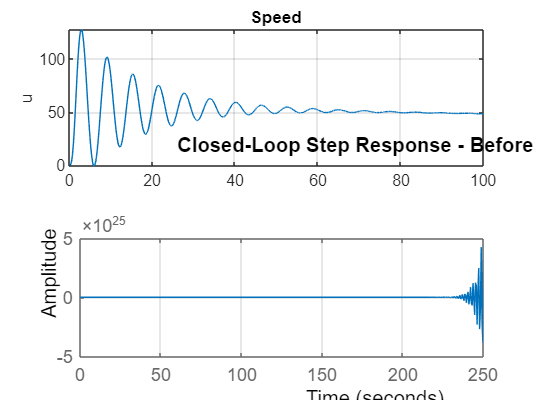

step(feedback(Gv_delta_r,1))
title('Closed-Loop Step Response - Before PID');
grid


% pidTuner(Gv_delta_r,'pid')

% Set Kp, Ki, and Kd values and create feedback loop

Kp4=0.01793;
Ki4=0.002629;
Kd4=0;
Cp4=pid(Kp4,Ki4,Kd4);
T4=feedback(Cp4*Gv_delta_r,1);

t=0:0.01:100;
disp('Fig 12. Closed-Loop Step Response After PID:');

Fig 12. Closed-Loop Step Response After PID:


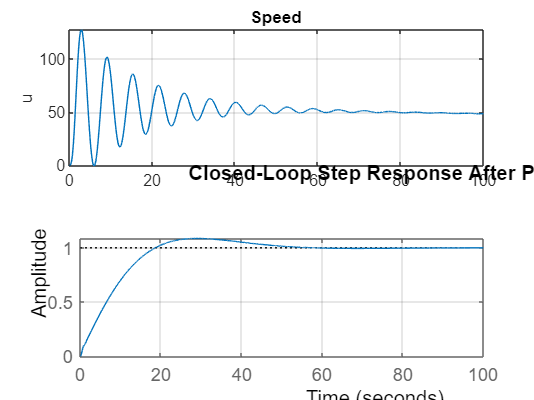

step(T4,t);
title('Closed-Loop Step Response After PID:');
grid

stepinfo(T4)

ans = struct with fields:
         RiseTime: 13.775
    TransientTime: 48.456
     SettlingTime: 48.456
      SettlingMin: 0.9121
      SettlingMax: 1.0869
        Overshoot: 8.6851
       Undershoot: 0
             Peak: 1.0869
         PeakTime: 28.998



% Steady state error

[y4,t]=step(T4);
ss_error4=abs(1-y4(end))

ss_error4 =     0.0043173
